# Carbon source Setting

% Creates versions of the base model in which only a set single carbon source is used
%The fol-lowing abbreviations denote the following: GLY for glycerol, ERY for erythritol, DARA for D-arabinose, LARA for L-arabinose, RIB for D-ribose, DXYL for D-xylose, LXYL for
%L-xylose, ADO for D-adonitol, MDX for methyl-_D-xylopyranose, GAL for D-galactose,
%GLU for glucose, FRU for fructose, MNE for D-mannose, SBE for L-sorbose, RHA for L-rhamnose, %DUL for dulcitol, INO for inositol, MAN for D-mannol, SOR for sorbitol,
%MDM for methyl-_D-mannopyranoside, MDG for methyl-_D-glucopyranoside, NAG for N-acetylglucosamine, AMY for amygdalin, ARB for arbutin, ESC for ferric acid, SAL for salicin,
%CEL for D-cellobiose, MAL for D-maltose, LAC for D-lactose, MEL for D-melibiose, SAC for D-saccharose, TRE for D-trehalose, INU for inulin, MLZ for D-melezitose, 
% RAF for D-Ra_nose, AMD for starch, GLYG for glycogen, XLT for xylitol, GEN for gentiobiose, TUR for D-turanose,
%Set Objective functions
%If looking to screen objectives other than production of biomass, this needs to be set below sugar choice for each manually
Model = changeObjective(Model,'biomass');
%This will be at a specific point (i.e. for biomass) in the 1167x1 cell)
rxn_posbiomass = strcmp(Model.rxns, 'biomass');
%Carbon sources 11955 should be able to grow on
%Set Sugar Choice
ModelGluc= Model;
ModelNoGluc= changeRxnBounds (Model,"EX_glc__D_e","0", "b");
ModelNoGluc= changeRxnBounds (ModelNoGluc,"GLC__Dtpts","0", "u");
ModelGLY= changeRxnBounds (ModelNoGluc,"EX_glyc_e","-10", "l");
ModelLARA= changeRxnBounds (ModelNoGluc,"EX_arab__L_e","-10", "l");
ModelRIB= changeRxnBounds (ModelNoGluc,"EX_rib__D_e","-10", "l");
ModelXyl= changeRxnBounds (ModelNoGluc,"EX_xyl__D_e","-10", "l");
ModelFRU= changeRxnBounds (ModelNoGluc,"EX_fru_e","-10", "l");
ModelMNE= changeRxnBounds (ModelNoGluc,"EX_man_e","-10", "l");
ModelRHA= changeRxnBounds (ModelNoGluc,"EX_rmn_e","-10", "l");
% No Mannol ModelMAN= changeRxnBounds (ModelNoGluc,"EX_xyl__D_e","-10", "l");
ModelSOR= changeRxnBounds (ModelNoGluc,"EX_sbt__D_e","-10", "l");
ModelMDG= changeRxnBounds (ModelNoGluc,"EX_mdgp_e","-10", "l");
% No unbonded N-Acetylglucosamine ModelNAG= changeRxnBounds (ModelNoGluc,"EX_xyl__D_e","-10", "l");
% No Amygdalin ModelAMY= changeRxnBounds (ModelNoGluc,"EX_xyl__D_e","-10", "l");
ModelARB= changeRxnBounds (ModelNoGluc,"EX_arbt_e","-10", "l");
%No Ferric acid, only Fe3+ ion ModelESC= changeRxnBounds (ModelNoGluc,"EX_xyl__D_e","-10", "l");
ModelSAL= changeRxnBounds (ModelNoGluc,"EX_salcn_e","-10", "l");
ModelCEL= changeRxnBounds (ModelNoGluc,"EX_cellb_e","-10", "l");
ModelMAL= changeRxnBounds (ModelNoGluc,"EX_malt_e","-10", "l");
ModelSAC= changeRxnBounds (ModelNoGluc,"EX_sucr_e","-10", "l");
ModelTRE= changeRxnBounds (ModelNoGluc,"EX_tre_e","-10", "l");
% Issue around polymeric starch ModelAMD= changeRxnBounds (ModelNoGluc,"R_EX_tre_e","-10", "l");
ModelGEN= changeRxnBounds (ModelNoGluc,"EX_gtbi_e","-10", "l");
ModelTUR= changeRxnBounds (ModelNoGluc,"EX_tura_e","-10", "l");
%Carbon sources 11955 should not be able to grow on

## FBA

%controls
FBAGluc = optimizeCbModel (Model,'max');
FBANosugar= optimizeCbModel(ModelNoGluc,'max');
%Other sugars
FBAGLY= optimizeCbModel(ModelGLY,'max');
FBALARA= optimizeCbModel(ModelLARA,'max');
FBARIB= optimizeCbModel(ModelRIB,'max'); 
FBAXyl= optimizeCbModel(ModelXyl,'max'); 
FBAFRU= optimizeCbModel(ModelFRU,'max'); 
FBAMNE= optimizeCbModel(ModelMNE,'max'); 
FBARHA= optimizeCbModel(ModelRHA,'max'); 
% No Mannol FBAMAN= optimizeCbModel(ModelMAN,'max'); 
FBASOR= optimizeCbModel(ModelSOR,'max'); 
FBAMDG= optimizeCbModel(ModelMDG,'max');
% No unbonded N-Acetylglucosamine FBANAG= optimizeCbModel (ModelNAG,'max'); 
% No Amygdalin FBAAMY= optimizeCbModel (ModelAMY,'max'); 
FBAARB= optimizeCbModel(ModelARB,'max'); 
%No Ferric acid, only Fe3+ ion FBAESC= optimizeCbModel(ModelESC,'max'); 
FBASAL= optimizeCbModel(ModelSAL,'max'); 
FBACEL= optimizeCbModel(ModelCEL,'max'); 
FBAMAL= optimizeCbModel(ModelMAL,'max'); 
FBASAC= optimizeCbModel(ModelSAC,'max'); 
FBATRE= optimizeCbModel(ModelTRE,'max'); 
% Issue around polymeric starch FBAAMD= optimizeCbModel(ModelAMD,'max'); 
FBAGEN= optimizeCbModel(ModelGEN,'max'); 
FBATUR= optimizeCbModel(ModelTUR,'max'); 

## Cross-Variable Vectors

%Vectors representing specifc reaction fluxes for biomass
%Biomass fluxes for carbon sources 11955 should be able to grow on
%BiomassY = [FBAGluc.v(rxn_posbiomass), FBANosugar.v(rxn_posbiomass), FBAARB.v(rxn_posbiomass), FBACEL.v(rxn_posbiomass), FBAFRU.v(rxn_posbiomass), FBAGEN.v(rxn_posbiomass), FBAGLY.v(rxn_posbiomass), FBALARA.v(rxn_posbiomass), FBAMAL.v(rxn_posbiomass), FBAMDG.v(rxn_posbiomass), FBAMNE.v(rxn_posbiomass), FBARHA.v(rxn_posbiomass), FBARIB.v(rxn_posbiomass), FBASAC.v(rxn_posbiomass), FBASAL.v(rxn_posbiomass), FBASOR.v(rxn_posbiomass), FBATRE.v(rxn_posbiomass), FBATUR.v(rxn_posbiomass), FBAXyl.v(rxn_posbiomass)];
% Currently, the model fails to grow on:: No sugar (control), Arbutin (ARB), L-Rhamnose (RHA) and Salicin (SAL). As a result, the 'Index exceeds Matrix Dimensions'.
% As I'm unaware how to tell it to put a zero in place if it can't grow, in the following line they have manually had a zero put in place:
BiomassY = [FBAGluc.v(rxn_posbiomass), 0, 0, FBACEL.v(rxn_posbiomass), FBAFRU.v(rxn_posbiomass), FBAGEN.v(rxn_posbiomass), FBAGLY.v(rxn_posbiomass), FBALARA.v(rxn_posbiomass), FBAMAL.v(rxn_posbiomass), FBAMDG.v(rxn_posbiomass), FBAMNE.v(rxn_posbiomass), 0, FBARIB.v(rxn_posbiomass), FBASAC.v(rxn_posbiomass), 0, FBASOR.v(rxn_posbiomass), FBATRE.v(rxn_posbiomass), FBATUR.v(rxn_posbiomass), FBAXyl.v(rxn_posbiomass)];
% Vector of sugar names (X axis)
%SugarnamesX = categorical({"Glucose", "No_sugar", "Arbutin", "Cellobiose", "Fructose", "Gentiobiose", "Glycerol", "L-Arabinose", "D-Maltose", "Methyl-D-glucoyranoside", "D-Mannose", "L-Rhamnose", "Ribose", "D-Saccharose", "Salicin", "Sorbitol", "D-Trehalose", "D-Turanose", "D-Xylose"});
SugarnamesX = categorical({'Glucose', 'No sugar', 'Arbutin', 'Cellobiose', 'Fructose', 'Gentiobiose', 'Glycerol', 'L-Arabinose', 'D-Maltose', 'Methyl-D-glucoyranoside', 'D-Mannose', 'L-Rhamnose', 'Ribose', 'D-Saccharose', 'Salicin', 'Sorbitol', 'D-Trehalose', 'D-Turanose', 'D-Xylose'});
%Biomass fluxes for carbon sources 11955 should not be able to grow on
%BiomassN = [];

## Carbon Source Graphing

x=SugarnamesX

x = 1×19 categorical array
     Glucose      No sugar      Arbutin      Cellobiose      Fructose      Gentiobiose      Glycerol      L-Arabinose      D-Maltose      Methyl-D-glucoyranoside      D-Mannose      L-Rhamnose      Ribose      D-Saccharose      Salicin      Sorbitol      D-Trehalose      D-Turanose      D-Xylose 


y=BiomassY

y =     0.7443         0         0    1.4961    0.7439    1.4961    0.4339    0.5740    1.4961    0.9372    0.7439         0    0.5740    1.4961         0    0.8112    1.4961    1.4961    0.5740


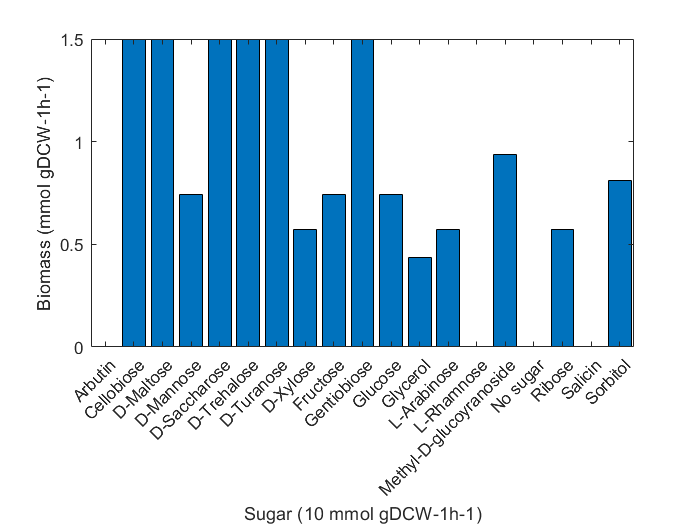

bar(x,y)
xlabel('Sugar (10 mmol gDCW-1h-1)')
ylabel('Biomass (mmol gDCW-1h-1)')